clear;
clc;
set(0,'defaulttextinterpreter','latex');

% Time increment and movement steps
time_increment = 60/110 * 1000; % converting to milliseconds
steps_left = 5;
steps_up = 6;
steps_right = 5;
steps_down = 6;
movement_distance = 0.7;

% Define the corners of the ground truth rectangle
x_true = [0, 3.50, 3.50, 0, 0];
y_true = [0.40, 0.40, 4.60, 4.60, 0.40];

node_x = [0, 3.5, 1.75];
node_y = [0, 0, 5.30];

figure;
idx = 1;
subplot_idx_raw = 1;
subplot_idx_filt = 2;

Colours = [
    0 0 1;
    0 1 0;
    1 0 1;
    0.34, 0.70, 0.91;
    0, 0.62, 0.45;
    0.80, 0.47, 0.65
    ];

% Loop through each file
for fileNum = 1:6
    % Construct the filename
    filename = sprintf('LSQ_FC132_Final%d.txt', fileNum);
    
    % Initialise arrays to hold the x, y, and t data
    x = [];
    y = [];
    t = [];
    
    % Open the file for reading
    fid = fopen(filename, 'r');
    
    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if line == -1
            break;
        end
        % Use regular expressions to extract the x, y, and t values
        matches = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+), t = (?<t>\d+)', 'names');
        if ~isempty(matches)
            x = [x; str2double(matches.x)]; %#ok<*AGROW> 
            y = [y; str2double(matches.y)];
            t = [t; str2double(matches.t)];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Generate the path taken
    path_x = [3.50];
    path_y = [0.40];
    path_t = [0; t(2)];
    for i = 1:(1000*1000/time_increment)
        if mod(i-1, steps_left + steps_up + steps_right + steps_down) < steps_left
            path_x(end+1, 1) = path_x(end) - movement_distance;
            path_y(end+1, 1) = path_y(end);
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up)
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) + movement_distance;
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up + steps_right)
            path_x(end+1, 1) = path_x(end) + movement_distance;
            path_y(end+1, 1) = path_y(end);
        else
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) - movement_distance;
        end
        path_t(end+1, 1) = path_t(end) + time_increment;
    end
    
    % Initialise error arrays
    error_x = [];
    error_y = [];
    error_t = [];
    total_error = [];
    
    % Find the matching time points and compute the errors
    for i = 1:length(t)
        [~, closestIndex] = min(abs(path_t - t(i)));
        if abs(path_t(closestIndex) - t(i)) <= 500 % time difference in milliseconds
            error_x(end+1, 1) = path_x(closestIndex) - x(i);
            error_y(end+1, 1) = path_y(closestIndex) - y(i);
            error_t(end+1, 1) = path_t(closestIndex) - t(i);
        end
    end

    for i = 1:length(error_x)
        total_error(i, 1) = sqrt(error_x(i).^2 + error_y(i).^2);
    end
    
    % Plot the data and errors for this file
    if fileNum < 4
        subplot(3, 2, subplot_idx_raw)
        plot(x, y, 'x', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));
        hold on;
        plot(x_true, y_true, 'k-', 'LineWidth', 1.5);
        plot(node_x, node_y, 'ro', 'LineWidth', 1.5, 'MarkerFaceColor','r');
        legend('W/o $\mathbf{\Omega}$ rejection', 'Ground Truth', 'Transmitter Nodes','Location', 'best', 'Interpreter', 'latex');
        title(sprintf('Trilateration without outlier rejection - Test %d', fileNum));
        subplot_idx_raw = subplot_idx_raw + 2;
    end
    if fileNum > 3
        subplot(3, 2, subplot_idx_filt)
        plot(x, y, '+', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));
        hold on;
        plot(x_true, y_true, 'k-', 'LineWidth', 1.5);
        plot(node_x, node_y, 'ro', 'LineWidth', 1.5, 'MarkerFaceColor','r');
        legend('With $\mathbf{\Omega}$ rejection', 'Ground Truth', 'Transmitter Nodes','Location', 'best', 'Interpreter', 'latex');
        title(sprintf('Trilateration with outlier rejection - Test %d', fileNum));
        subplot_idx_filt = subplot_idx_filt + 2;
    end
    xlabel('$x$ [m]');
    ylabel('$y$ [m]');
    grid on;
    hold off;
    
    % Display the error for this file
    fprintf('Test %d errors:\n', fileNum);
%     disp('Errors in x:');
%     disp(error_x);
%     disp('Errors in y:');
%     disp(error_y);
%     disp('Mean error x:')
%     disp(mean(error_x))
%     disp('Mean error y:')
%     disp(mean(error_y))
%     disp('Std error x:')
%     disp(std(error_x))
%     disp('Std error y:')
%     disp(std(error_y))
%     disp('Quartiles error x:')
%     disp(quantile(error_x, [0.25 0.5 0.75 0.9]))
%     disp('Quartiles error y:')
%     disp(quantile(error_y, [0.25 0.5 0.75 0.9]))

%     disp('Mean x:')
%     disp(mean(x))
%     disp('Mean y:')
%     disp(mean(y))
%     disp('Std x:')
%     disp(std(x))
%     disp('Std y:')
%     disp(std(y))
%     disp('Quartiles x:')
%     disp(quantile(x, [0.25 0.5 0.75 0.9]))
%     disp('Quartiles y:')
%     disp(quantile(y, [0.25 0.5 0.75 0.9]))

    disp('Mean total error:')
    disp(mean(total_error))
    disp('STD total error:')
    disp(std(total_error))
    disp('Minimum total error:')
    disp(min(total_error))
    disp('Maximum total error:')
    disp(max(total_error))
    disp('Range')
    disp(range(total_error))
    disp('Quartiles Total Error:')
    disp(quantile(total_error, [0.25 0.5 0.75 0.9]))
    disp('IQR:')
    disp(iqr(total_error))
end

Test 1 errors:


Mean total error:


    4.5968



STD total error:


    2.3652



Minimum total error:


   6.0000e-09



Maximum total error:


   14.2397



Range


   14.2397



Quartiles Total Error:


    2.9656    4.1640    6.0566    7.5917



IQR:


    3.0910



Test 2 errors:


Mean total error:


    6.6397



STD total error:


    4.5177



Minimum total error:


   6.0000e-09



Maximum total error:


   29.1500



Range


   29.1500



Quartiles Total Error:


    3.5748    5.8000    8.9133   12.3306



IQR:


    5.3385



Test 3 errors:


Mean total error:


    5.7018



STD total error:


    3.7009



Minimum total error:


   6.0000e-09



Maximum total error:


   30.0793



Range


   30.0793



Quartiles Total Error:


    3.4662    4.9200    7.0047    9.7070



IQR:


    3.5384



Test 4 errors:


Mean total error:


    4.4774



STD total error:


    1.8857



Minimum total error:


   6.0000e-09



Maximum total error:


    9.8723



Range


    9.8723



Quartiles Total Error:


    3.2035    4.7048    5.6944    6.6564



IQR:


    2.4909



Test 5 errors:


Mean total error:


    3.3628



STD total error:


    1.7101



Minimum total error:


   6.0000e-09



Maximum total error:


    8.2486



Range


    8.2486



Quartiles Total Error:


    2.0154    3.2604    4.5144    5.6133



IQR:


    2.4990



Test 6 errors:


Mean total error:


    3.8550



STD total error:


    2.0748



Minimum total error:


   6.0000e-09



Maximum total error:


   10.2851



Range


   10.2851



Quartiles Total Error:


    2.2760    3.4617    5.3394    6.8503



IQR:


    3.0634



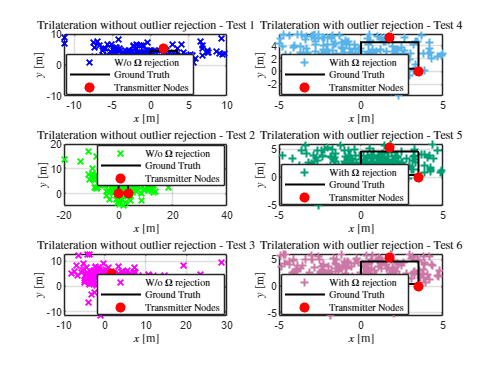


% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 27]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 27];

% Save the figure with the specified resolution
print(fig, 'LSQ_Trilateration', '-depsc', '-r600'); % '-depsc' is used for EPS color

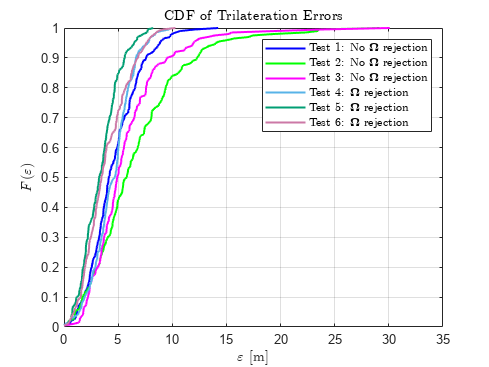

clear;
clc;
set(0,'defaulttextinterpreter','latex', 'DefaultLegendInterpreter', 'latex');

% Time increment and movement steps
time_increment = 60/110 * 1000; % converting to milliseconds
steps_left = 5;
steps_up = 6;
steps_right = 5;
steps_down = 6;
movement_distance = 0.7;

% Define the corners of the ground truth rectangle
x_true = [0, 3.50, 3.50, 0, 0];
y_true = [0.40, 0.40, 4.60, 4.60, 0.40];

node_x = [0, 3.5, 1.75];
node_y = [0, 0, 5.30];

figure;
idx = 1;
subplot_idx_raw = 1;
subplot_idx_filt = 2;

Colours = [
    0 0 1;
    0 1 0;
    1 0 1;
    0.34, 0.70, 0.91;
    0, 0.62, 0.45;
    0.80, 0.47, 0.65
    ];

% marker_styles = {'x', 'x', 'x', '+', '+', '+'};

% Loop through each file
for fileNum = 1:6
    % Construct the filename
    filename = sprintf('LSQ_FC132_Final%d.txt', fileNum);
    
    % Initialise arrays to hold the x, y, and t data
    x = [];
    y = [];
    t = [];
    
    % Open the file for reading
    fid = fopen(filename, 'r');
    
    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if line == -1
            break;
        end
        % Use regular expressions to extract the x, y, and t values
        matches = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+), t = (?<t>\d+)', 'names');
        if ~isempty(matches)
            x = [x; str2double(matches.x)]; %#ok<*AGROW> 
            y = [y; str2double(matches.y)];
            t = [t; str2double(matches.t)];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Generate the path taken
    path_x = [3.50];
    path_y = [0.40];
    path_t = [0; t(2)];
    for i = 1:(1000*1000/time_increment)
        if mod(i-1, steps_left + steps_up + steps_right + steps_down) < steps_left
            path_x(end+1, 1) = path_x(end) - movement_distance;
            path_y(end+1, 1) = path_y(end);
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up)
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) + movement_distance;
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up + steps_right)
            path_x(end+1, 1) = path_x(end) + movement_distance;
            path_y(end+1, 1) = path_y(end);
        else
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) - movement_distance;
        end
        path_t(end+1, 1) = path_t(end) + time_increment;
    end
    
    % Initialise error arrays
    error_x = [];
    error_y = [];
    error_t = [];
    total_error = [];
    
    % Find the matching time points and compute the errors
    for i = 1:length(t)
        [~, closestIndex] = min(abs(path_t - t(i)));
        if abs(path_t(closestIndex) - t(i)) <= 500 % time difference in milliseconds
            error_x(end+1, 1) = path_x(closestIndex) - x(i);
            error_y(end+1, 1) = path_y(closestIndex) - y(i);
            error_t(end+1, 1) = path_t(closestIndex) - t(i);
        end
    end

    for i = 1:length(error_x)
        total_error(i, 1) = sqrt(error_x(i).^2 + error_y(i).^2);
    end

    sorted_errors = sort(total_error);            % Sort the errors
    n = length(sorted_errors);                     % Number of error points
    p = (1:n)'/n;                                  % Probabilities for each point
    
    plot(sorted_errors, p, '-', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));  % Plot CDF
    grid on;
    xlabel('$\varepsilon$ [m]');
    ylabel('$F(\varepsilon)$');
    title('CDF of Trilateration Errors');
    hold on
    
%     % Display the error for this file
%     fprintf('Test %d errors:\n', fileNum);
%     disp('Mean total error:')
%     disp(mean(total_error))
%     disp('STD total error:')
%     disp(std(total_error))
%     disp('Minimum total error:')
%     disp(min(total_error))
%     disp('Maximum total error:')
%     disp(max(total_error))
%     disp('Range')
%     disp(range(total_error))
%     disp('Quartiles Total Error:')
%     disp(quantile(total_error, [0.25 0.5 0.75 0.9]))
%     disp('IQR:')
%     disp(iqr(total_error))
end

hold off
legend('Test 1: No $\mathbf{\Omega}$ rejection', 'Test 2: No $\mathbf{\Omega}$ rejection', 'Test 3: No $\mathbf{\Omega}$ rejection', 'Test 4: $\mathbf{\Omega}$ rejection', 'Test 5: $\mathbf{\Omega}$ rejection', 'Test 6: $\mathbf{\Omega}$ rejection')

% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 12]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 12];

% Save the figure with the specified resolution
print(fig, 'LSQ_Trilateration_CDF', '-depsc', '-r600'); % '-depsc' is used for EPS color